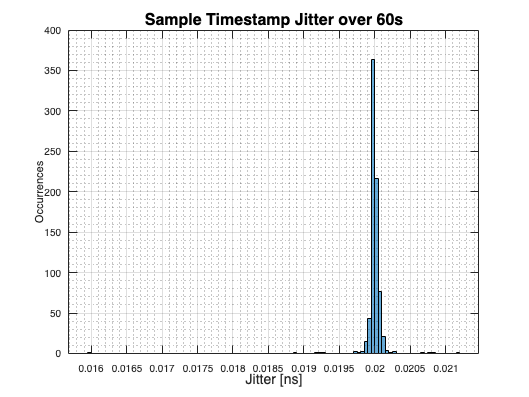

folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);

%% CLOSED LOOP DC MOTOR
[~, cl_ramp_rps, cl_ramp_ref, cl_ramp_u] = extractMotorData("DataSets/cl_zn_ramp10.csv");
[timestamps, cl_step_rps, cl_step_ref, cl_step_u ] = extractMotorData("DataSets/cl_zn_step.csv");
[~, cl_chirp_rps, cl_chirp_ref, cl_chirp_u] = extractMotorData("DataSets/cl_zn_chrip8_1.csv");

% Calculate Sample Time Jitter
histogram(diff(timestamps) * 1e-9); grid on; grid minor; 
xlabel("Jitter [ns]", 'FontSize', 14); ylabel('Occurrences'); 
title('Sample Timestamp Jitter over 60s', 'FontSize', 16);

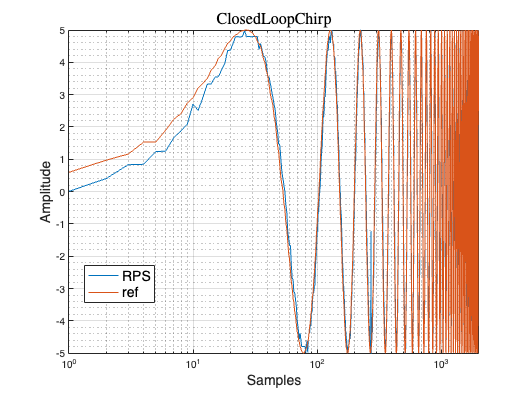


fig = figure;
graphData(cl_chirp_rps(1001:3001), cl_chirp_ref(1001:3001), 'ClosedLoopChirp', folderpath, true);

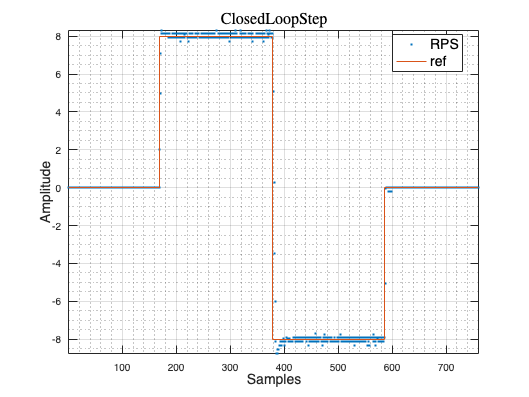

graphData(cl_step_rps, cl_step_ref, 'ClosedLoopStep', folderpath ,false);

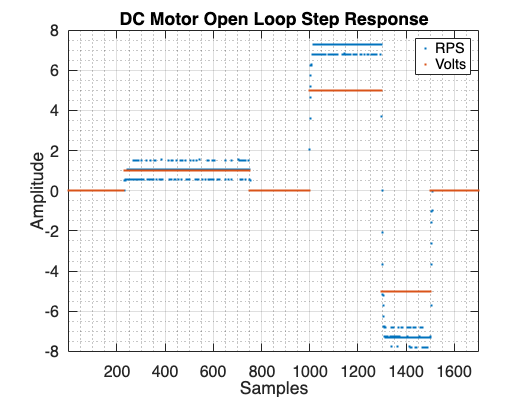




%% OPEN LOOP DC MOTOR
[~, ramp_rps, ramp_volt, ~] = extractMotorData("DataSets/ramp10_100.csv");
[~, sin1_1_rps, sin1_1_volt, ~] = extractMotorData("DataSets/sin_1_1_100.csv");
[~, sin5_5_rps, sin5_volt, ~] = extractMotorData("DataSets/sin_5_5_100.csv");
[~, sin1_8_rps, sin1_8_volt, ~] = extractMotorData("DataSets/sin_1_8_100.csv");
[~, ~,data ]  = parseDataSet("DataSets/closedChirp.csv");
chirp_rps = data(:, 12);
chirp_volt= data(:,13);
[~, step_rps, step_volt, ~] = extractMotorData("DataSets/openStep.csv");
[~, trig_rps, trig_volt, ~] = extractMotorData("DataSets/openTrig.csv");

fig = figure;
plot(step_rps(200:end), '.'); hold on; 
plot(step_volt(200:end), '.'); hold off; 
legend("RPS", "Volts"); grid on; grid minor;
set(gca, 'FontSize', 16);
title("DC Motor Open Loop Step Response"); 
xlabel("Samples"); ylabel("Amplitude"); xlim([1, 1700]);
exportgraphics(fig, fullfile(folderpath, "OpenLoopStep.pdf"));

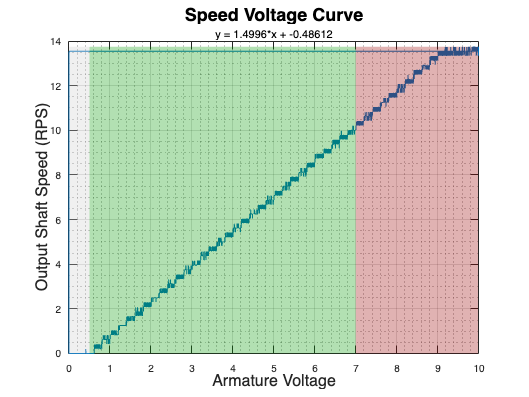


% Speed Voltage Curve 
fig = figure;
plot(ramp_volt,ramp_rps); 
hold on;

c = polyfit(ramp_volt, ramp_rps,1);
subtitle(['y = ' num2str(c(1)) '*x + ' num2str(c(2))]);

% Define Nominal Operation Section
x_start = 0.5; 
x_width = 6.5;
y_min = min(ramp_rps);
y_max = max(ramp_rps);
y_height = y_max - y_min;
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.0 0.6 0 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% Define Overdrive Section
x_start = 7; 
x_width = max(ramp_volt) - x_start;
y_min = min(ramp_rps);
y_max = max(ramp_rps);
y_height = y_max - y_min;
% Draw rectangle (semi-transparent red)
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.6 0.0 0 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% Define DeadZone Section
x_start = 0; 
x_width = 0.5;
y_min = min(ramp_rps);
y_max = max(ramp_rps);
y_height = y_max - y_min;
% Draw rectangle (semi-transparent red)
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.8 0.8 0.8 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');


grid on; grid minor; 
title("Speed Voltage Curve", 'FontSize',18); 
ylabel("Output Shaft Speed (RPS)", 'FontSize',16); 
xlabel("Armature Voltage", 'FontSize',16);
hold off;
figure('Position', [100,100, 1600, 800]);
exportgraphics(fig, fullfile(folderpath, "SpeedVoltageCurve.pdf"));


% Plot datasets
graphData(trig_rps, trig_volt, 'Trig', folderpath, false);

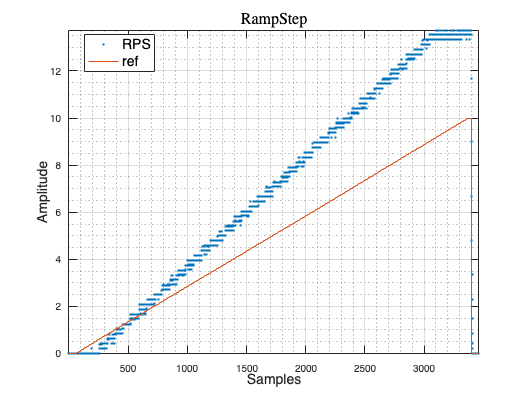

graphData(ramp_rps, ramp_volt, 'RampStep', folderpath, false);

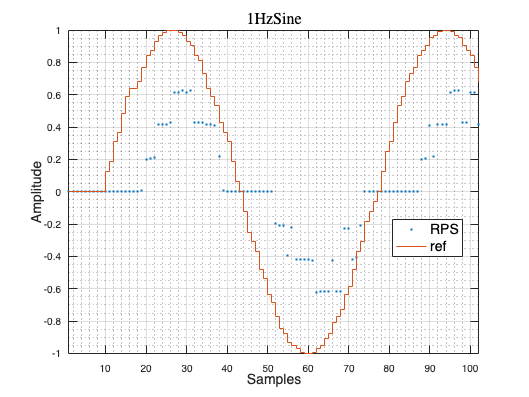

graphData(sin1_1_rps(100:201), sin1_1_volt(100:201), '1HzSine', folderpath, false);

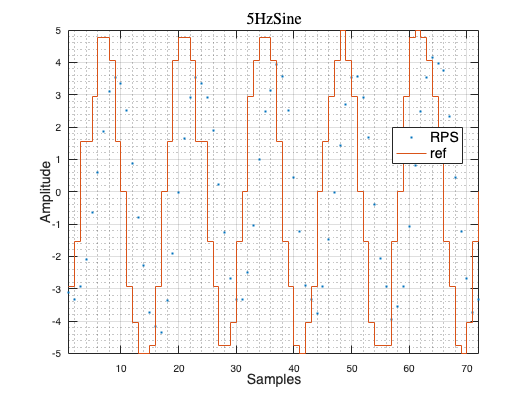

graphData(sin5_5_rps(75:146), sin5_volt(75:146), '5HzSine', folderpath, false);

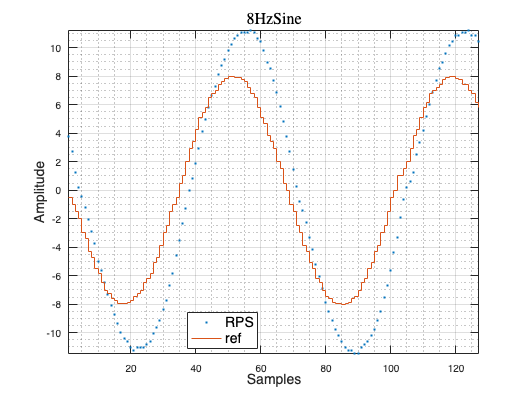

graphData(sin1_8_rps(75:201), sin1_8_volt(75:201), '8HzSine', folderpath, false);

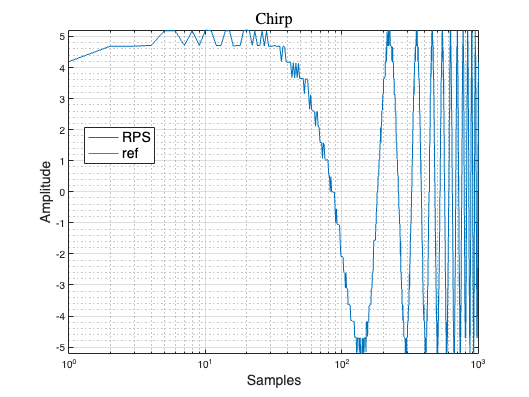

graphData(chirp_rps(1:1001), zeros, 'Chirp', folderpath ,true);


% Input-output plotting helper function
function graphData(outputData, inputData, plotTitle, folderpath, log)
    if(log == true)

    fig = figure;
    semilogx(outputData)
    hold on;
    semilogx(inputData, '-');
    hold off;

    
    end

    if(log ==false)

    fig = figure;
    stairs(outputData, '.');
    hold on;
    stairs(inputData, '-');
    hold off;
    
    end
    grid on; grid minor;
    title(plotTitle, 'FontSize', 16, 'Interpreter', 'latex'); 
    legend("RPS", "ref", 'FontSize', 14, 'Location', 'best');
    xlabel('Samples', 'FontSize', 14);
    ylabel('Amplitude', 'FontSize', 14);
    axis tight;
    
    % Export plot
    filepath = fullfile(folderpath, plotTitle + ".pdf");
    exportgraphics(fig, filepath);
end
